%%%% Data to sound test file with self-generated data

% %% Portion of script that plays sound once target is detected in angle range. Uses hypothetical data matrix of target's angle and distance from the radar
% ydata = rand(10,2) + 1i*rand(10,2)
% rx_angle = angle(ydata)*(180/pi)
% target_angle = zeros(10,1);
% for i = 1:1:10
%     target_angle(i,1) = rx_angle(i,1) - rx_angle(i,2)
%     if (target_angle(i) > 0) || (target_angle(i) < 0)
%         play(player); % Refers to chosen audio file at beginning of code
%         % insert code for Karplus Strong Algorithm % another option is to
%         % use the K-S algorithm rather than an audio file
%         %pause(2) % wait 10 seconds before moving on to the next line
%     else
%         stop(player); % Refers to chosen audio file at beginning of code
%         %pause(10) % wait 10 seconds before moving on to the next line
%     end
% end
% stop(player)

%% Data to sound test file - part 2 - plays certain pitches of a guitar string as the angle beamwidth changes. Uses hypothetical data matrix of target's angle and distance from the radar
ydata = rand(10,2) + 1i*rand(10,2)

ydata =    0.0090 + 0.5279i   0.2516 + 0.2608i
   0.7183 + 0.2560i   0.1335 + 0.4931i
   0.4494 + 0.4087i   0.5645 + 0.8558i
   0.6596 + 0.9475i   0.5410 + 0.7244i
   0.7532 + 0.9193i   0.0689 + 0.1991i
   0.8047 + 0.1212i   0.9884 + 0.1573i
   0.0292 + 0.5919i   0.2511 + 0.3705i
   0.7798 + 0.3597i   0.3155 + 0.8623i
   0.5674 + 0.7193i   0.3007 + 0.6848i
   0.0761 + 0.5236i   0.0420 + 0.6342i


rx_angle = angle(ydata)*(180/pi)

rx_angle =    89.0249   46.0309
   19.6180   74.8554
   42.2835   56.5928
   55.1561   53.2479
   50.6707   70.9069
    8.5679    9.0415
   87.1802   55.8719
   24.7592   69.9043
   51.7355   66.2953
   81.7280   86.2076


target_angle =    42.9940
         0
         0
         0
         0
         0
         0
         0
         0
         0


target_angle =    42.9940
  -55.2374
         0
         0
         0
         0
         0
         0
         0
         0


target_angle =    42.9940
  -55.2374
  -14.3093
         0
         0
         0
         0
         0
         0
         0


target_angle =    42.9940
  -55.2374
  -14.3093
    1.9082
         0
         0
         0
         0
         0
         0


target_angle =    42.9940
  -55.2374
  -14.3093
    1.9082
  -20.2362
         0
         0
         0
         0
         0


target_angle =    42.9940
  -55.2374
  -14.3093
    1.9082
  -20.2362
   -0.4736
         0
         0
         0
         0


target_angle =    42.9940
  -55.2374
  -14.3093
    1.9082
  -20.2362
   -0.4736
   31.3083
         0
         0
         0


target_angle =    42.9940
  -55.2374
  -14.3093
    1.9082
  -20.2362
   -0.4736
   31.3083
  -45.1451
         0
         0


target_angle =    42.9940
  -55.2374
  -14.3093
    1.9082
  -20.2362
   -0.4736
   31.3083
  -45.1451
  -14.5598
         0


target_angle =    42.9940
  -55.2374
  -14.3093
    1.9082
  -20.2362
   -0.4736
   31.3083
  -45.1451
  -14.5598
   -4.4796


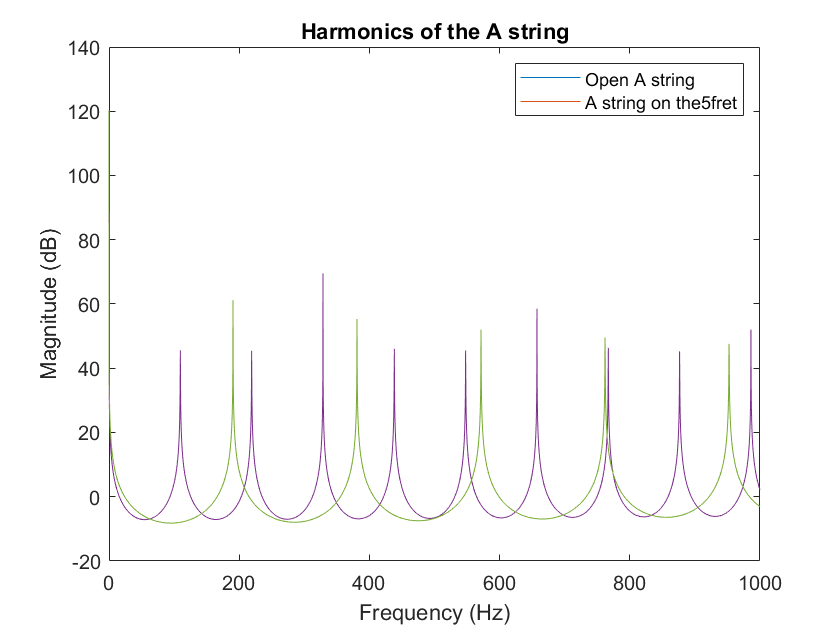

target_angle = zeros(10,1);
syms fret_value
for i = 1:1:10
    target_angle(i,1) = rx_angle(i,1) - rx_angle(i,2)
    if (target_angle(i,1) > 10) && (target_angle(i,1) < 25)
        fret_value = 15;
    elseif (target_angle(i,1) > -25) && (target_angle(i,1) < -10)
        fret_value = 5;
    elseif (target_angle(i,1) >= -10) && (target_angle(i,1) >= 10)
        fret_value = 10;
    end
    if (target_angle(i,1)>-25) && (target_angle(i,1)<25)
        Fs       = 44100;
        A        = 110; % The A string of a guitar is normally tuned to 110 Hz
        Eoffset  = -5;
        Doffset  = 5;
        Goffset  = 10;
        Boffset  = 14;
        E2offset = 19;
        F = linspace(1/Fs, 1000, 2^12);
        x = zeros(Fs*4, 1);
        delay = round(Fs/A);
        b  = firls(42, [0 1/delay 2/delay 1], [0 0 1 1]);
        a  = [1 zeros(1, delay) -0.5 -0.5];
        [H,W] = freqz(b, a, F, Fs);
        plot(W, 20*log10(abs(H)));
        title('Harmonics of an open A string');
        xlabel('Frequency (Hz)');
        ylabel('Magnitude (dB)');
        zi = rand(max(length(b),length(a))-1,1);
        note = filter(b, a, x, zi);
        note = note-mean(note);
        note = note/max(abs(note));
        % hplayer = audioplayer(note, Fs); play(hplayer)
        
        fret  = 4;
        delay = round(Fs/(A*2^(fret/fret_value)));
        
        b  = firls(42, [0 1/delay 2/delay 1], [0 0 1 1]);
        a  = [1 zeros(1, delay) -0.5 -0.5];
        
        [H,W] = freqz(b, a, F, Fs);
        hold on
%         plot(W, 20*log10(abs(H)));
%         title('Harmonics of the A string');
%         legend(['Open A string'], ['A string on the ',num2str(fret_value),' fret']);
        zi = rand(max(length(b),length(a))-1,1);
        note = filter(b, a, x, zi);
        note = note-mean(note);
        note = note/max(note);
        hplayer = audioplayer(note, Fs); play(hplayer)
        pause(2)
    end
end